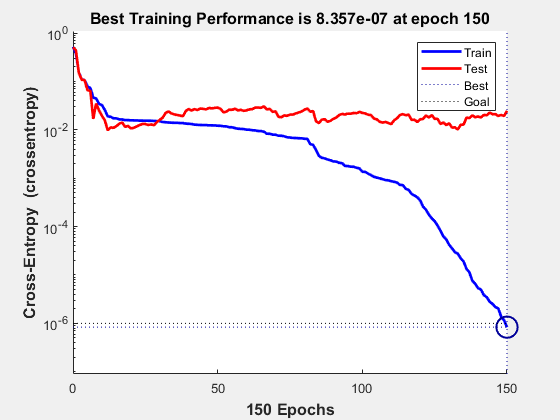

% Demo program na klasifikaciu IRIS kvetov do 3 skupin na základe styroch vlastností V1, V2, V3, V4 
% NS má 4 vstupy veliciny V1,V2,V3,V4  a 3 výstupy o rozsahu 0-1, 
% kde hodnota 1  na prislusnom vystupe hovori do ktorej skupiny je dany bod klasifikovany

echo on

% nacitanie dat
[X,P]=iris_dataset;

% vytvorenie štruktúry NS 
% 1 skryta vrstva s poctom neuronov 12 funkciou 'tansig'
net = patternnet(12);

% nastavenie parametrov trenovania
% net.performFcn = 'mse';             % priemer sumy štvorcov odchýliek - nastavená kriterialna funkcia
net.performFcn ='crossentropy';         % crossentropy - krizova  entropia
net.trainParam.goal = 0.000001;	    % Ukoncovacia podmienka na chybu SSE.
net.trainParam.epochs = 1000;  	    % Max. pocet trénovacích cyklov.
net.trainParam.min_grad=1e-12;      % Ukoncovacia podmienka na min. gradient

% nahodne rozdelenie dat
net.divideFcn='dividerand';
net.divideParam.trainRatio=0.6; % 60% trenovacie
net.divideParam.valRatio=0;
net.divideParam.testRatio=0.4;  % 40% testovacie

[net,tr] = train(net,X,P);       % trenovanie siete

% zobrazenie chyby siete pocas trenovania
plotperform(tr)


Y=sim(net,X)               % simulacia NS

Y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

classes = vec2ind(Y)       % zaradenie do tried

classes =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


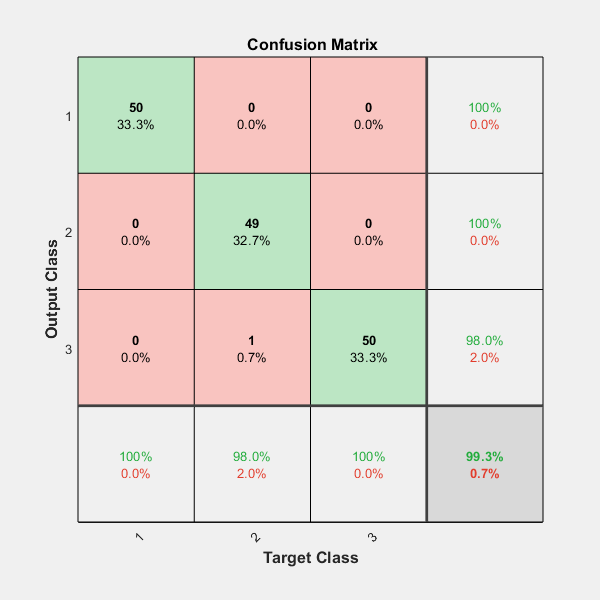


plotconfusion(P,Y)         % porovnanie, spravne / nespravne klasifikovanych vzoriek - kontingencna tabulka

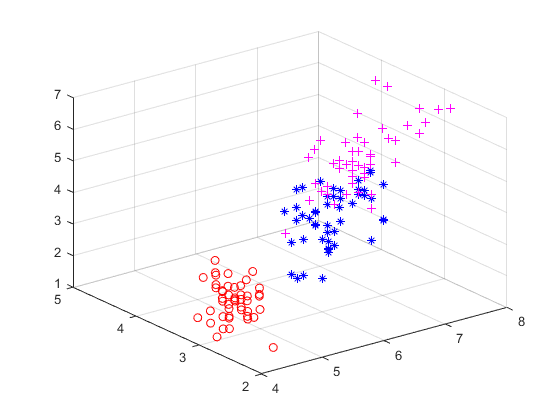


echo off

% overenie nahodne vsetkych dat
h=figure;
title('Iris data')
axis([4 8 2 4.5 1 7])


for k=1:length(classes)
    indx=classes(k);
    if indx==1
        plot3(X(1,k),X(2,k),X(3,k),'ro')
    elseif indx==2
        plot3(X(1,k),X(2,k),X(3,k),'b*')
    else
        plot3(X(1,k),X(2,k),X(3,k),'m+')
    end
    hold on
end

grid on